# HW7

*Steven Henderson*

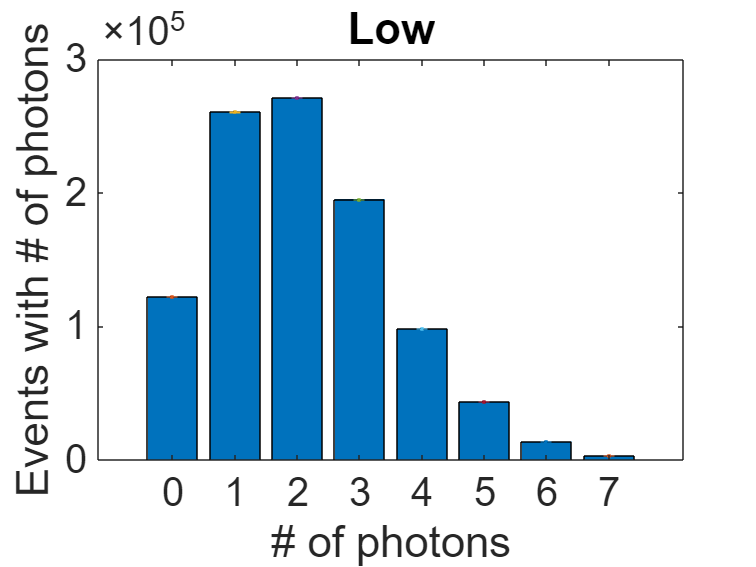

% Read data for xlsx files
c_high = readmatrix('PhotonCountingHigh.xlsx')  ;
c_low = readmatrix('PhotonCountingLow.xlsx') ;
% Plot bar graph
figure 
bar(c_low(:, 1), c_low(:, 2)) %
set(gca,'fontsize',22)
hold on ;
errorbar(c_low(:, 1), c_low(:, 2), sqrt( sqrt(sum(c_low(:, 2)))),'.')
hold off;
xlabel('# of photons')
ylabel('Events with # of photons')
title('Low')

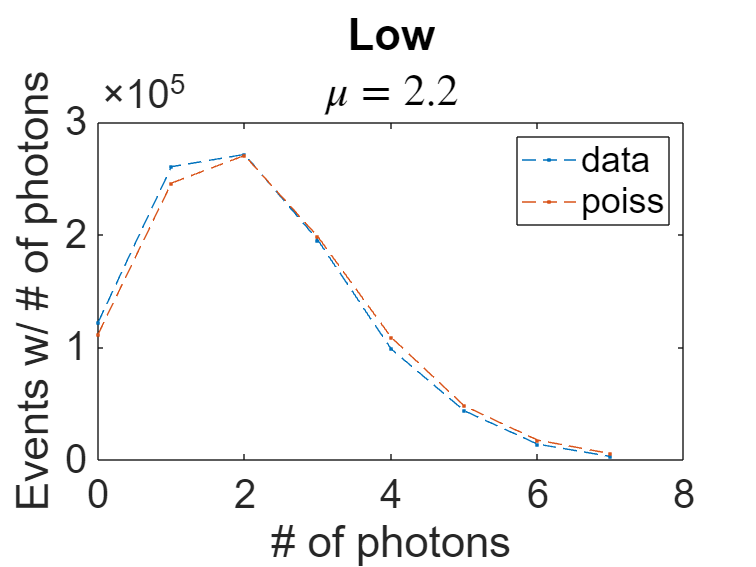

% Get Poisson's distribution for our low dataset
y = poisspdf(c_low(:, 1), 2.2) ; % mean = 2.2
% Plot Poisson's distribution vs. actual data scalling Poisson's by N
% counts
figure 
plot(c_low(:, 1), c_low(:, 2), '--.')
set(gca,'fontsize',22)
hold on ;
plot(c_low(:, 1), y*sum(c_low(:, 2)), '--.') % Poisson's scaled
hold off;
xlabel('# of photons')
title('Low')
legend('data', 'poiss')
ylabel('Events w/ # of photons')
subtitle('$\mu=2.2$', 'Interpreter', ' latex')

**2.**

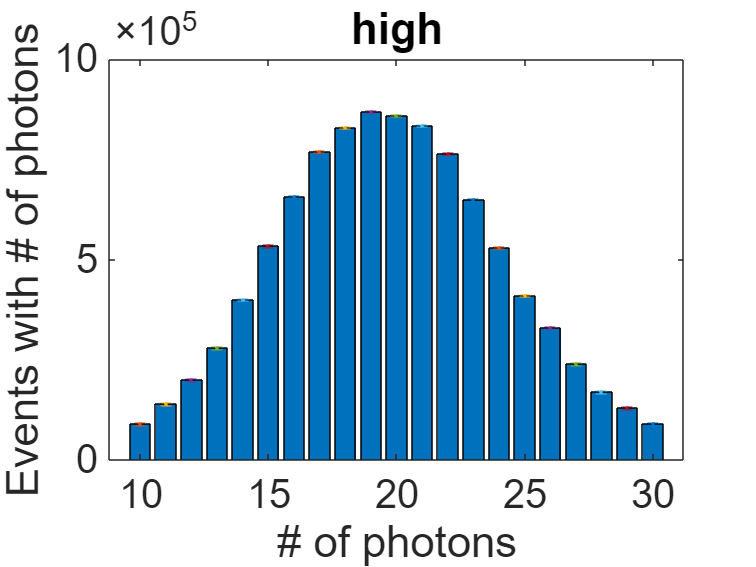

% Plot high dataset
figure 
bar(c_high(:, 1), c_high(:, 2)) %
set(gca,'fontsize',22)
hold on ;
errorbar(c_high(:, 1), c_high(:, 2), sqrt(sum(c_high(:, 2))),'.')
hold off;
xlabel('# of photons')
ylabel('Events with # of photons')
title('high')

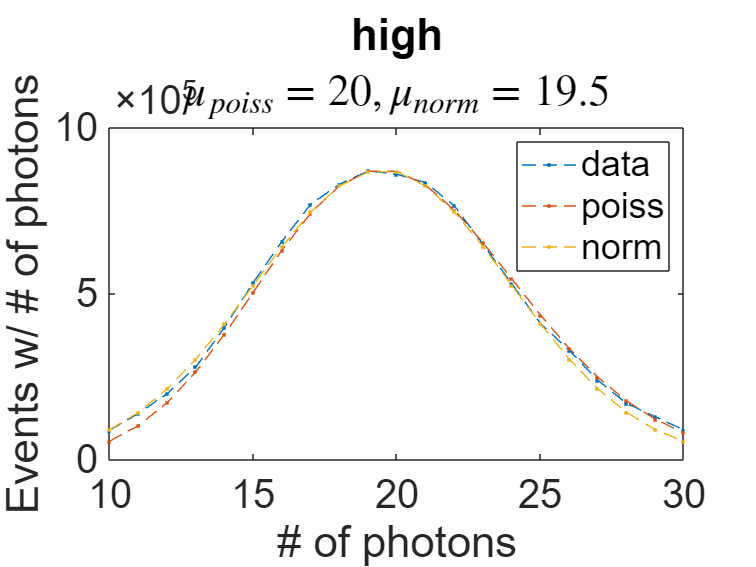

% Get Poisson's distribution
y = poisspdf(c_high(:, 1), 20) ; % mean = 20
norm = normpdf(c_high(:, 1), 19.5, sqrt(20)) ; % mean = 19.5, std_dev=sqrt(20)
% Plot Poisson's distrubtions, the normal distribution, and the dataset to
% fit by eye
figure 
plot(c_high(:, 1), c_high(:, 2), '--.')
set(gca,'fontsize',22)
hold on ;
plot(c_high(:, 1), y*sum(c_high(:, 2)), '--.')
plot(c_high(:, 1), norm*sum(c_high(:, 2)), '--.')
hold off;
legend('data', 'poiss', 'norm')
xlabel('# of photons')
ylabel('Events w/ # of photons')
title('high')
subtitle('$\mu_{poiss}=20, \mu_{norm}=19.5$', 'Interpreter', 'latex')

**Analysis for figure above:**

 Above it is shown that the mean from the Poisson's distribution is 20 and 19.5 for the Normal distribtion with a std. deviation of sqrt(20). The difference betweens means here is likely due to poisson's discrete nature and the normals continuous nature conflicting. It is interesting that the std. deviation uses the mean from Poisson's to fit better instead of the mean from the normal distribtuion.

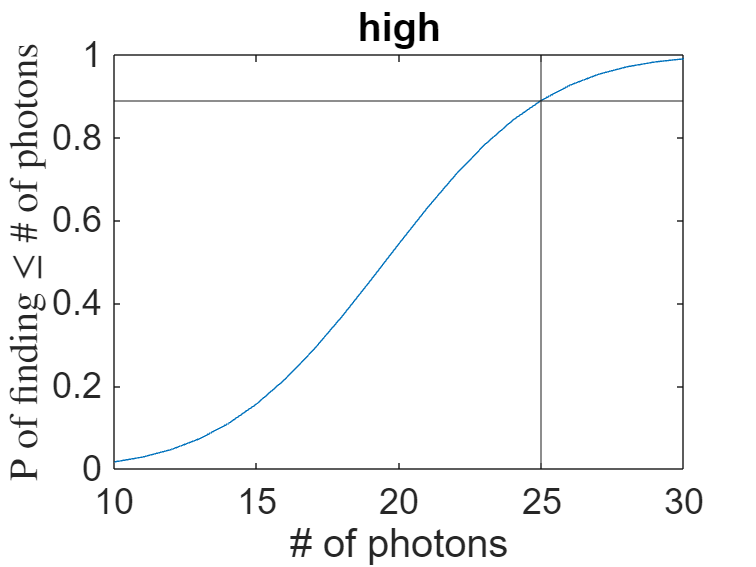

% Get cumilative distribution of the normal function found above
cnorm = cdf('Normal', c_high(:, 1), 19.5, sqrt(20)) ;
plot(c_high(:, 1), cnorm)
xlabel('# of photons')
ylabel('P of finding$\leq$\# of photons', 'Interpreter', 'latex')
title('high')
set(gca, 'fontsize', 20)
xline(25)
yline(0.89) % P = 89%

**Analysis for above figure:**

Above is the cumlative distribution function of the normal distribution and it is shown that the chances of finding 25 or less photons in an event is 89%.